# Overview of the COVID-19 pandemic in Mexico during the study period

Weekly average of daily new reported cases from January 2021 to June 2022

## Import epidemiological reports (total cases in the country)

opts = delimitedTextImportOptions("NumVariables", 2, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Week", "Cases_MEX"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Casos_MEX = readtable("/MATLAB Drive/Analisis de datos MARTEC/Casos_MEX.csv", opts)

Casos_MEX = 79x2 table
    Week    Cases_MEX
    ____    _________

      1      5180.5  
      2       15467  
      3       15741  
      4       14819  
      5       12590  
      6      8590.1  
      7      7406.9  
      8      6081.1  
      9        6040  
     10      5678.4  
     11      4844.3  
     12      4010.3  
     13      4069.4  
     14      2938.9  
     15      3803.6  
     16        3318  


clear opts

## Present the data as a semi-log plot

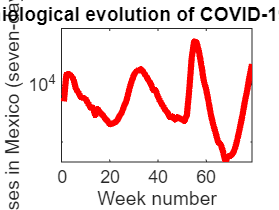

semilogy(Casos_MEX,"Week","Cases_MEX","LineStyle","-","LineWidth",3,"Color","r")
xlabel("Week number")
ylabel("Daily cases in Mexico (seven-day average)")
title("Epidemiological evolution of COVID-19 in Mexico")